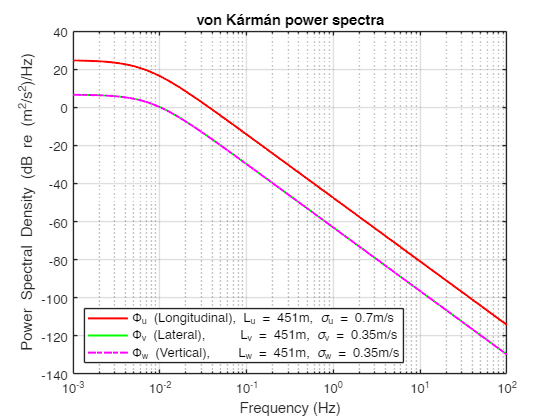

% von Karman spectra

clear; clc; close all;

% TURBULENCE MODEL: k-Epsilon
%% --- Parameters ---

V_hub = 25.7222;     % Mean wind speed at hub height (m/s) (
Lu = 451;       % Longitudinal turbulence length scale (m)  
Lv = 451;    % Lateral turbulence length scale (m)
Lw = 451;    % Vertical turbulence length scale (m)

sigma_u = 0.7; % Longitudinal turbulence intensity (standard deviation, m/s)
sigma_v = sigma_u/2;     % Lateral turbulence intensity (m/s) 
sigma_w = sigma_u/2;     % Vertical turbulence intensity (m/s)

%% --- Frequency Range ---
f = logspace(-3, 2, 500); % Frequency range (Hz) - from 0.01 Hz to 100 Hz
omega = 2 * pi * f;       % Angular frequency (rad/s)

%% --- Von Karman Power Spectral Density Functions ---

% Longitudinal component (u)
Su_func = @(omega, V, L, sigma) (2 * sigma^2 * L / V) ./ (1 + (1.339 * L * omega ./ V).^2).^(5/6);

% Lateral component (v)
Sv_num_term1 = @(omega, V, L, sigma) (sigma^2 * L / V);
Sv_num_term2 = @(omega, V, L) (1 + (4/3) * (1.339 * L * omega ./ V).^2);
Sv_den = @(omega, V, L) (1 + (1.339 * L * omega ./ V).^2).^(11/6);
Sv_func = @(omega, V, L, sigma) Sv_num_term1(omega, V, L, sigma) .* Sv_num_term2(omega, V, L) ./ Sv_den(omega, V, L);

% Vertical component (w)
% The vertical component has the same functional form as the lateral component
Sw_num_term1 = @(omega, V, L, sigma) (sigma^2 * L / V);
Sw_num_term2 = @(omega, V, L) (1 + (4/3) * (1.339 * L * omega ./ V).^2);
Sw_den = @(omega, V, L) (1 + (1.339 * L * omega ./ V).^2).^(11/6);
Sw_func = @(omega, V, L, sigma) Sw_num_term1(omega, V, L, sigma) .* Sw_num_term2(omega, V, L) ./ Sw_den(omega, V, L);

%% --- Calculate PSDs ---
Phi_u_linear = Su_func(omega, V_hub, Lu, sigma_u);
Phi_v_linear = Sv_func(omega, V_hub, Lv, sigma_v);
Phi_w_linear = Sw_func(omega, V_hub, Lw, sigma_w);

% --- Convert PSD to dB ---
% Using a small epsilon to prevent log10(0) if any PSD value is extremely close to zero,
% though von Karman spectra are generally positive.
epsilon = 1e-12; % A small number to avoid log10(0)
Phi_u_dB = 20 * log10(Phi_u_linear + epsilon);
Phi_v_dB = 20 * log10(Phi_v_linear + epsilon);
Phi_w_dB = 20 * log10(Phi_w_linear + epsilon);

%% --- Plotting ---
figure;
semilogx(f, Phi_u_dB, 'r-', 'LineWidth', 1.5);
hold on;
semilogx(f, Phi_v_dB, 'g', 'LineWidth', 1.5);
semilogx(f, Phi_w_dB, 'm-.', 'LineWidth', 1.5);
hold off;

% --- Formatting the Plot ---
title('von Kármán power spectra', 'FontSize', 14);
xlabel('Frequency (Hz)', 'FontSize', 12);
ylabel('Power Spectral Density (dB re (m^2/s^2)/Hz)', 'FontSize', 12); % Updated Y-label
legend({['\Phi_u (Longitudinal), L_u = ' num2str(Lu) 'm, \sigma_u = ' num2str(sigma_u,2) 'm/s'], ...
        ['\Phi_v (Lateral),     L_v = ' num2str(Lv) 'm, \sigma_v = ' num2str(sigma_v,2) 'm/s'], ...
        ['\Phi_w (Vertical),    L_w = ' num2str(Lw) 'm, \sigma_w = ' num2str(sigma_w,2) 'm/s']}, ...
        'Location', 'southwest', 'FontSize', 10); % A
grid on;
set(gca, 'FontSize', 10);
xlim([f(1) f(end)]); % Ensure the x-axis covers the defined frequency range

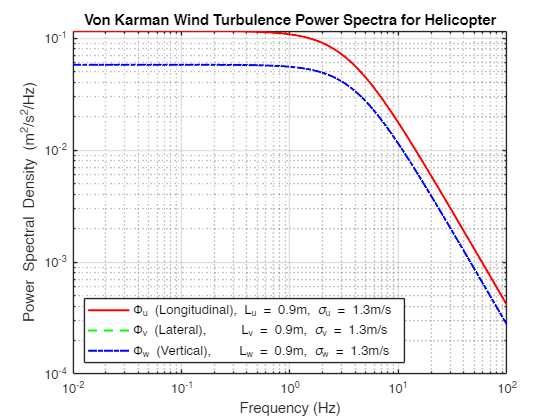

%% --- Frequency Range ---
f = logspace(-2, 2, 500); % Frequency range (Hz) - from 0.01 Hz to 100 Hz
omega = 2 * pi * f;       % Angular frequency (rad/s)

%% --- Von Karman Power Spectral Density Functions ---

% Longitudinal component (u)
Su = @(omega, V, L, sigma) (2 * sigma^2 * L / V) ./ (1 + (1.339 * L * omega ./ V).^2).^(5/6);

% Lateral component (v)
Sv_num_term1 = @(omega, V, L, sigma) (sigma^2 * L / V);
Sv_num_term2 = @(omega, V, L) (1 + (4/3) * (1.339 * L * omega ./ V).^2);
Sv_den = @(omega, V, L) (1 + (1.339 * L * omega ./ V).^2).^(11/6);
Sv = @(omega, V, L, sigma) Sv_num_term1(omega, V, L, sigma) .* Sv_num_term2(omega, V, L) ./ Sv_den(omega, V, L);

% Vertical component (w)
% The vertical component has the same functional form as the lateral component
% if Lv = Lw and sigma_v = sigma_w. For generality, we'll write it separately.
Sw_num_term1 = @(omega, V, L, sigma) (sigma^2 * L / V);
Sw_num_term2 = @(omega, V, L) (1 + (4/3) * (1.339 * L * omega ./ V).^2);
Sw_den = @(omega, V, L) (1 + (1.339 * L * omega ./ V).^2).^(11/6);
Sw = @(omega, V, L, sigma) Sw_num_term1(omega, V, L, sigma) .* Sw_num_term2(omega, V, L) ./ Sw_den(omega, V, L);


%% --- Calculate PSDs ---
Phi_u = Su(omega, V_hub, Lu, sigma_u);
Phi_v = Sv(omega, V_hub, Lv, sigma_v);
Phi_w = Sw(omega, V_hub, Lw, sigma_w);

%% --- Plotting ---
figure;
loglog(f, Phi_u, 'r-', 'LineWidth', 1.5);
hold on;
loglog(f, Phi_v, 'g--', 'LineWidth', 1.5);
loglog(f, Phi_w, 'b-.', 'LineWidth', 1.5);
hold off;

% --- Formatting the Plot ---
title('Von Karman Wind Turbulence Power Spectra for Helicopter', 'FontSize', 14);
xlabel('Frequency (Hz)', 'FontSize', 12);
ylabel('Power Spectral Density (m^2/s^2/Hz)', 'FontSize', 12);
legend({['\Phi_u (Longitudinal), L_u = ' num2str(Lu) 'm, \sigma_u = ' num2str(sigma_u,2) 'm/s'], ...
        ['\Phi_v (Lateral),     L_v = ' num2str(Lv) 'm, \sigma_v = ' num2str(sigma_v,2) 'm/s'], ...
        ['\Phi_w (Vertical),    L_w = ' num2str(Lw) 'm, \sigma_w = ' num2str(sigma_w,2) 'm/s']}, ...
        'Location', 'southwest', 'FontSize', 10);
grid on;
set(gca, 'FontSize', 10);
xlim([f(1) f(end)]); % Ensure the x-axis covers the defined frequency range


% --- Display Parameters on Plot (Optional) ---
dim = [.2 .5 .3 .3]; % Position for text box [x y w h]
str = {['Mean Wind Speed (V_{hub}): ' num2str(V_hub) ' m/s']};
% annotation('textbox',dim,'String',str,'FitBoxToText','on', 'BackgroundColor', 'white');
